## Estimating the Rate of Change from Experimental Data

In many biological experiments, we do not know the exact equation describing a process. Instead, we collect measurements at discrete time points.

A researcher measures the number of cells in a culture every 12 hours.

Questions:

- When is the growth rate highest?

- How fast is the cell population growing at each time point?

### Let's get the data into variables

time = [0 12 24 36 48 60 72];
cells = [1200 1650 2450 3800 5600 7300 8100];

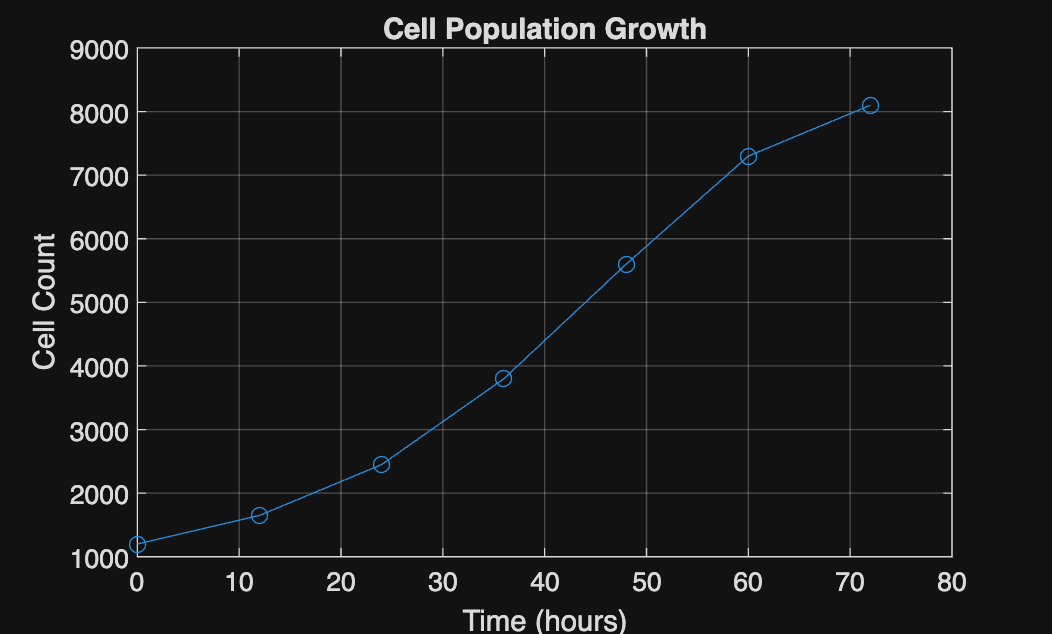

plot(time, cells, '-o')

xlabel('Time (hours)')
ylabel('Cell Count')
title('Cell Population Growth')
grid on

### But we don't have an equation to differentiate!

Recall that a derivative tells us *how much a quantity changes as its input changes*.

The `diff()` function computes the difference between consecutive elements.

cellDifference = diff(cells)

cellDifference =          450         800        1350        1800        1700         800


Next, compute the time elapsed between consecutive measurements.

timeDifference = diff(time)

timeDifference =     12    12    12    12    12    12


Finally, divide the two to estimate the growth rate.

growthRate = cellDifference ./ timeDifference

growthRate =    37.5000   66.6667  112.5000  150.0000  141.6667   66.6667


Notice that `diff()` estimates the growth rate **between** measurements, so we need to plot the values at the **midpoints** of each interval. 

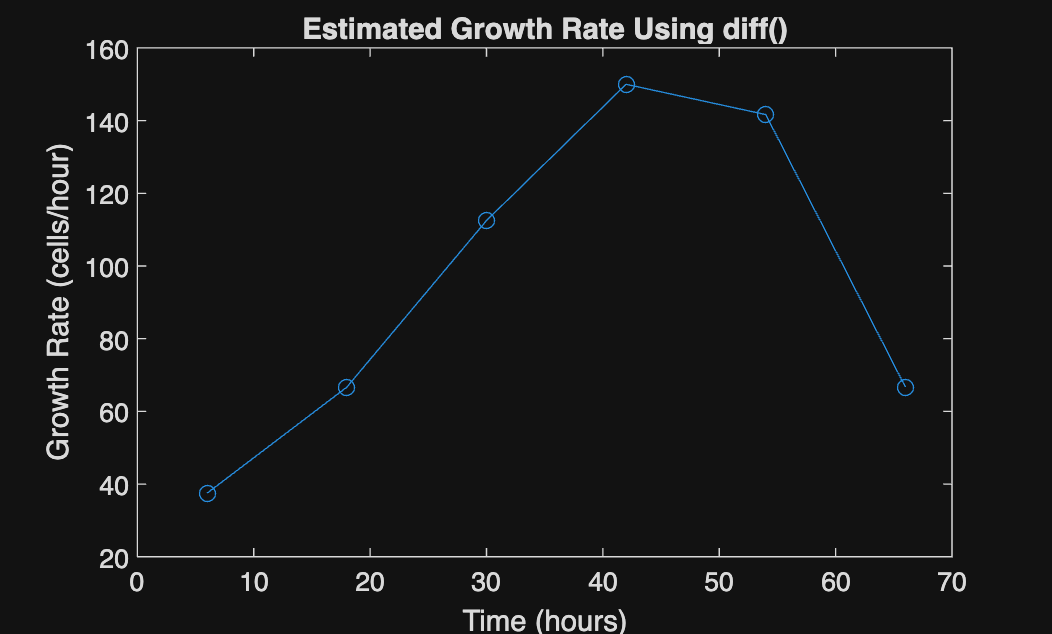

timeMid = (time(1:end-1) + time(2:end)) / 2;
plot(timeMid, growthRate, '-o')
xlabel('Time (hours)')
ylabel('Growth Rate (cells/hour)')
title('Estimated Growth Rate Using diff()')

### There is a better way to do this

The `gradient()` function approximates the growth rate at every time point.

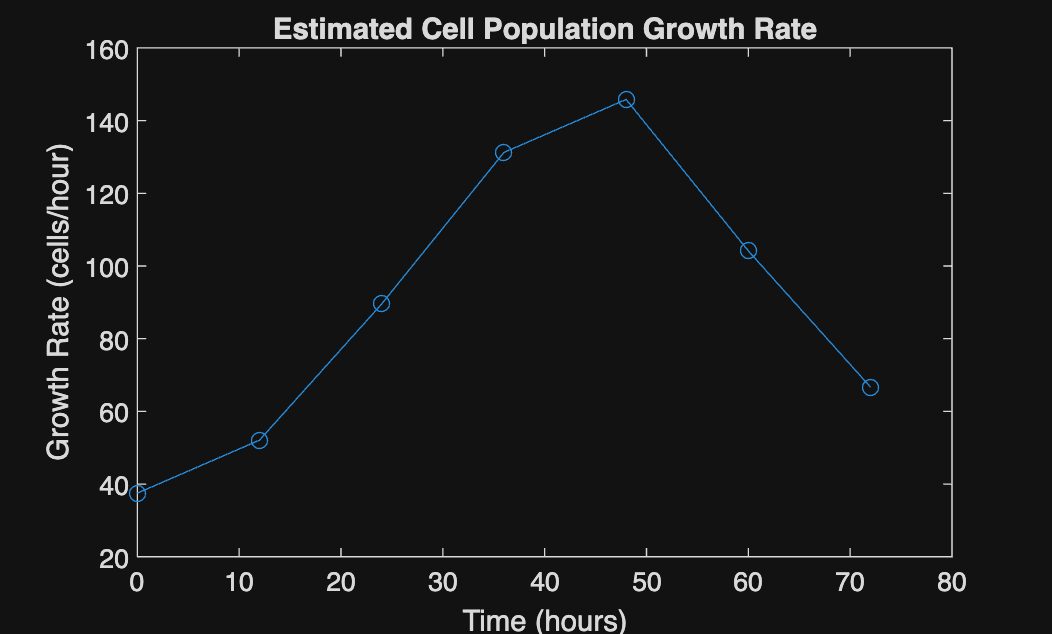

growthRate = gradient(cells, time);

plot(time, growthRate, '-o')

xlabel('Time (hours)')
ylabel('Growth Rate (cells/hour)')
title('Estimated Cell Population Growth Rate')

### What was the maximum growth rate?

[maxGrowthRate, idx] = max(growthRate);

fprintf('Maximum growth rate: %.2f cells/hour\n', maxGrowthRate);

Maximum growth rate: 145.83 cells/hour


fprintf('Observed at %.0f hours.\n', time(idx));

Observed at 48 hours.
